% Code by Ayush Agarwal , ECE , 2nd year 
% Team ARcheus , I-CHIP22 PS1 

% This code is for getting the output text file 
% ( which has output 1d array with hex values)
% convert it to image and display it 

% opening the output text file which came from verilog

% setting up the file id for applying functions
fileID = fopen('output.txt','r');

% setting the specifications for reading the file
% since we used %x here , hence hex got converted to 
% decimals automatically 
formatSpec = '%x ';
sizeO = [256 384];
O = fscanf(fileID,formatSpec,sizeO)

O =    174   175   176   177   178   179   179   178   175   177   175   169   163   157   147   137   137   137   136   136   136   135   135   135   134   133   132   131   131   131   131   131   133   133   132   132   132   131   131   131   131   131   131   132   132   133   133   133   132   133
   180   180   182   183   184   184   183   183   180   182   179   173   167   160   149   139   137   137   137   136   136   136   135   135   136   135   134   134   133   133   134   134   133   133   133   132   132   132   131   131   133   133   133   134   134   134   135   135   133   134
   188   189   191   192   192   191   190   189   187   189   186   179   172   164   152   141   138   138   137   137   137   136   136   136   139   138   137   136   136   136   136   137   134   134   133   133   133   132   132   132   132   132   132   133   133   134   134   134   134   134
   198   199   200   201   200   199   197   195   194   195   192   184   176   167   154   


% it was in float , so converting it to uint8
O = uint8(O)

O = 256×384 uint8 matrix
   174   175   176   177   178   179   179   178   175   177   175   169   163   157   147   137   137   137   136   136   136   135   135   135   134   133   132   131   131   131   131   131   133   133   132   132   132   131   131   131   131   131   131   132   132   133   133   133   132   133
   180   180   182   183   184   184   183   183   180   182   179   173   167   160   149   139   137   137   137   136   136   136   135   135   136   135   134   134   133   133   134   134   133   133   133   132   132   132   131   131   133   133   133   134   134   134   135   135   133   134
   188   189   191   192   192   191   190   189   187   189   186   179   172   164   152   141   138   138   137   137   137   136   136   136   139   138   137   136   136   136   136   137   134   134   133   133   133   132   132   132   132   132   132   133   133   134   134   134   134   134
   198   199   200   201   200   199   197   195   194   195   192   184

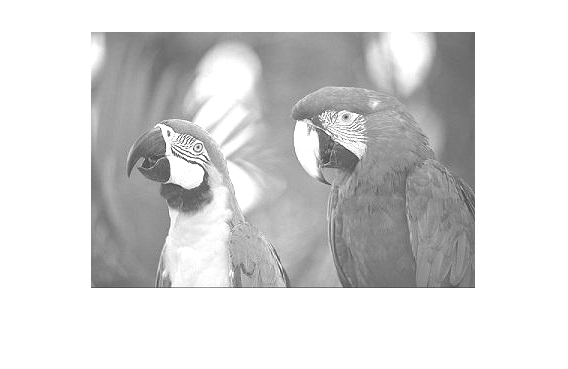


% showing the image 
imshow(O)


imwrite(O,'output_image.jpg')
% Garbage code 
%output_array = load('output.txt')
%output_array = hex2dec(output_array)
%imagesc(output_array)
%O = mat2gray(O,[0 255])
%image(O)